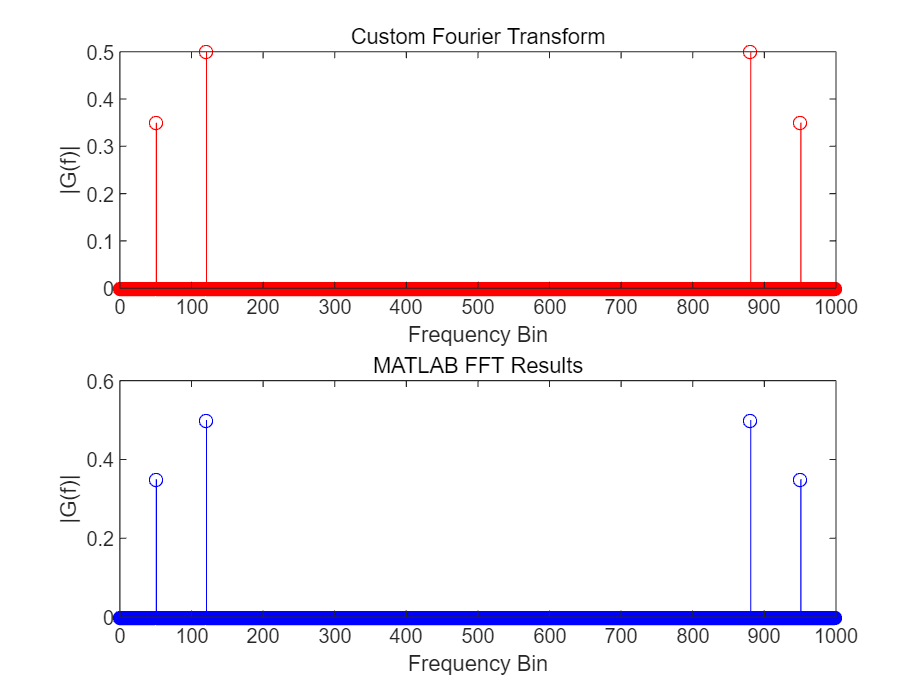

% 임의의 파형 데이터 생성
fs = 1000; % 샘플링 주파수, Hz
t = 0:1/fs:1-1/fs; % 1초 동안의 시간 벡터
x = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t); % 두 개의 사인 파형 합성

% 사용자 정의 푸리에 변환 함수 사용
G_custom = second_DFT(x, t);
%% X_custom = first_DFT(x);

% MATLAB 내장 fft 함수 사용
G_fft = fft(x) / length(x);

% 결과 출력
figure;
subplot(2,1,1);
stem(abs(G_custom), 'r'); % 사용자 정의 푸리에 변환 결과의 크기
title('Custom Fourier Transform');
xlabel('Frequency Bin');
ylabel('|G(f)|');

subplot(2,1,2);
stem(abs(G_fft), 'b'); % MATLAB fft 결과의 크기
title('MATLAB FFT Results');
xlabel('Frequency Bin');
ylabel('|G(f)|');


% 두 결과의 차이 계산 및 출력
difference = G_custom - G_fft;
disp('Difference between Custom and MATLAB FFT:');

Difference between Custom and MATLAB FFT:


disp(difference);

  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.3500i  -0.0000 + 0.0000i   0.0000 - 


% 차이의 절대값의 최대값을 출력하여 비교의 정확도를 나타냄
disp('Maximum difference (absolute value):');

Maximum difference (absolute value):


disp(max(abs(difference)));

    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.8500    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000